**Setting up some data**

Variable [raw_total_filament_data] (line1) is randomized data that is supposed to be used to create the displacement vectors (x,y,z) that would be distributed throughout the whole segment

             However variable [total_filament_data] (line12) is just the unit vectors from variable [raw_total_filament_data], I mostly use this because unit vectors overall are much easier to multiply with a length of whatever we choose

             Likewise, the variable [spherical_coord_position_data] is just variable [total_filament_data] in <x,y,z> translated into spherical coordinates <phi,theta,rho>

variables [i] -> [iiiii] are supposed to be used to "annotate"/ assign values to the rows of the data set to be used to calculate later values such as derivatives throughout the segment


raw_total_filament_data=rand(10,3);
[e,u]=size(raw_total_filament_data);

i=1:e;
ii=2:e;
iii=1:e-1;
iiii=1:e-2;
iiiii=2:e-1;

rho_squared=raw_total_filament_data(i,1).^2.+raw_total_filament_data(i,2).^2.+raw_total_filament_data(i,3).^2;
total_filament_data_xyz=raw_total_filament_data(i,:)./sqrt(rho_squared)

total_filament_data_xyz =     0.9519    0.2850    0.1123
    0.5986    0.2629    0.7567
    0.5657    0.3370    0.7526
    0.1788    0.3575    0.9166
    0.8439    0.3354    0.4187
    0.1379    0.9737    0.1812
    0.1416    0.7412    0.6561
    0.0867    0.4884    0.8683
    0.4923    0.6393    0.5907
    0.4501    0.5672    0.6897


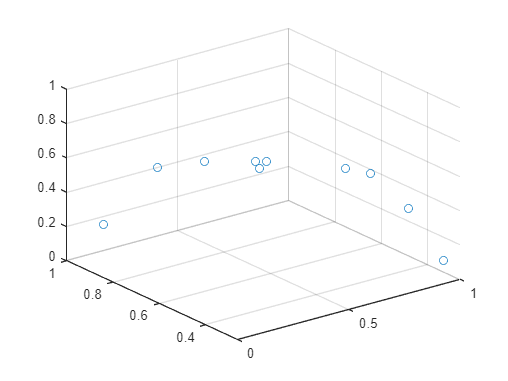


x=total_filament_data_xyz(:,1);
y=total_filament_data_xyz(:,2);
z=total_filament_data_xyz(:,3);

scatter3(x,y,z)


total_rho=sqrt(x.^2+y.^2+z.^2);
total_theta=acos(z./total_rho);
total_phi=asin(y./(total_rho.*sin(total_theta)));
spherical_coord_position_data=[total_phi,total_theta,total_rho]

spherical_coord_position_data =     0.2909    1.4582    1.0000
    0.4138    0.7126    1.0000
    0.5372    0.7188    1.0000
    1.1070    0.4112    1.0000
    0.3782    1.1388    1.0000
    1.4301    1.3885    1.0000
    1.3821    0.8551    1.0000
    1.3952    0.5191    1.0000
    0.9146    0.9388    1.0000
    0.9000    0.8098    1.0000


**Setting up variables/data for use in a coupling matrix:**

Quick note of variables and meanings:

As described in the Capturing 3-D large strain Euler...

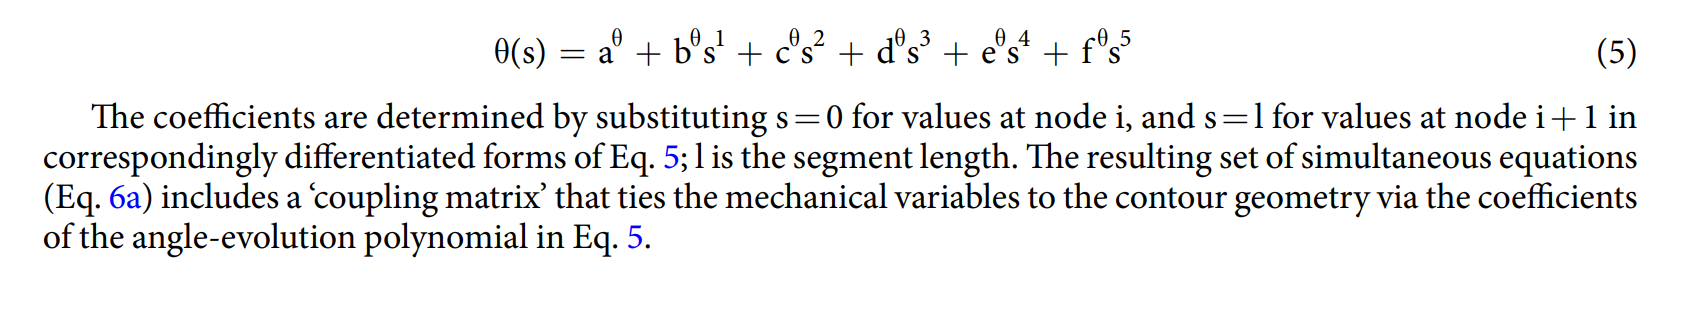<----- we are trying to solve for this equation's coefficients (a,b,c,d...)

variable [l] (line25) is supposed to represent the full length of the fiber segment that we are looking at (for now still at the first one)

variable [s] (line26) is supposed to represent a "tracking variable" that follows along the length of variable [l]

variable [s_interval] (line29) is supposed to represent the spacing between the variable [s] values, which will be used to calculate the derivatives

To solve for the coefficients in the theta(s) equations, the following coupling matrix was provided:

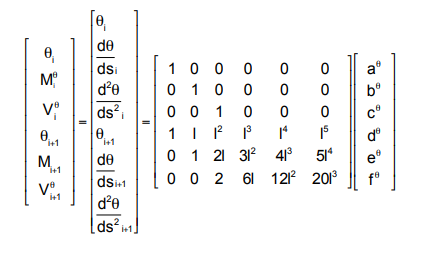

variable [total_theta] (line31) is just taken from the  variable[spherical_coord_position_data]'s theta column

variable [total_deriv_theta] (line32) represents the derivative of the [total_theta] variable, which is caculated by 

to provide the derivative of theta at variable [s]=[0,...,l] 

The same steps were done over again with the variable [total_deriv_theta] to give us the new variable [total_second_deriv_theta] (line33)

*note variable [i],[ii],...[iiiii] are used to run the calculations on different parts fo the matrix, because when using linear approximation to find the derivatives of theta, the data sets will lose 1 value...

                    example: if variable   theta=[3,2,1]    , its corresponding derivative matrix will lose a value    derivative_theta=[1,1]

the variable [theta_i] (line34)  should be the first theta value from the variable [total_theta] (on line 31) likewise for variables [deriv_theta_i] (line36) [total_deriv_theta] (line 32) should be first first derivative theta value from variable [total_deriv_theta] (line32) and first second derivative theta value from variable [total_second_deriv_theta] (line33)

the variables [theta_iplus1] (line35), [deriv_theta_iplus1] (line37), [second_deriv_theta_iplus1] (line39) should be the end values of the second values from the variables [total_theta] (on line 31, [total_deriv_theta] (line 32), [total_second_deriv_theta] (line33)

l=0.7

l = 0.7000

s=0:0.1:l

s =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000


horiz_s=s'

horiz_s =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000


[tot_s,~]=size(horiz_s)

tot_s = 8

s_interval=s(1,2)

s_interval = 0.1000


total_theta=acos(z./total_rho)

total_theta =     1.4582
    0.7126
    0.7188
    0.4112
    1.1388
    1.3885
    0.8551
    0.5191
    0.9388
    0.8098


total_deriv_theta=(total_theta(iii)-total_theta(ii))./s_interval

total_deriv_theta =     7.4566
   -0.0619
    3.0753
   -7.2755
   -2.4976
    5.3345
    3.3604
   -4.1976
    1.2904


total_second_deriv_theta=(total_deriv_theta(iiiii)-total_deriv_theta(iiii))./s_interval

total_second_deriv_theta =   -75.1844
   31.3722
 -103.5079
   47.7790
   78.3207
  -19.7413
  -75.5799
   54.8803


theta_i=total_theta(1,1)

theta_i = 1.4582

theta_iplus1=total_theta(end,1)

theta_iplus1 = 0.8098

deriv_theta_i=total_deriv_theta(1,1)

deriv_theta_i = 7.4566

deriv_theta_iplus1=total_deriv_theta(end,1)

deriv_theta_iplus1 = 1.2904

second_deriv_theta_i=total_second_deriv_theta(1,1)

second_deriv_theta_i = -75.1844

second_deriv_theta_iplus1=total_second_deriv_theta(end,1)

second_deriv_theta_iplus1 = 54.8803

**Solving the Coupling matrix for Theta:**

To solve the coupling matrix to obtain the coefficients in the theta(s) function, I rearranged the original matrix

 as follows, where [a^theta, b^theta, c^theta, d^theta,...] are the coefficients

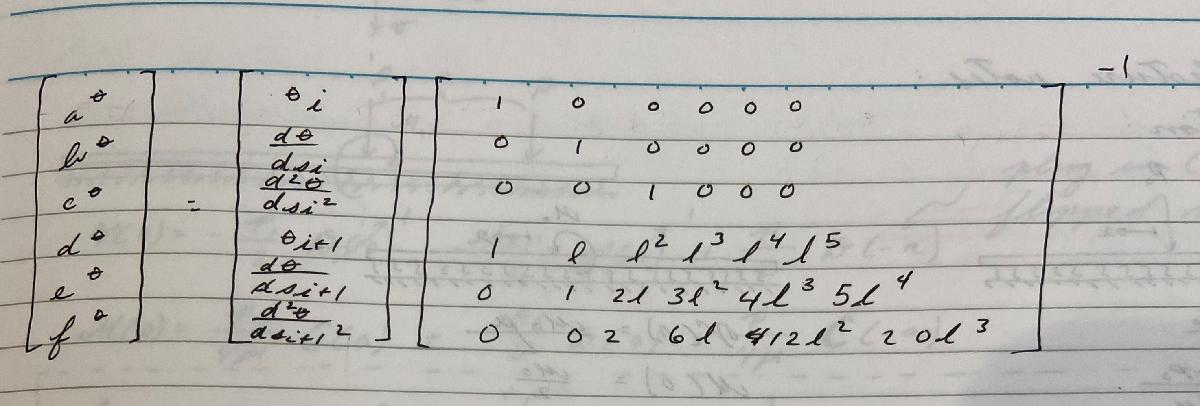

variable [a] (line41)  is supposed to be this  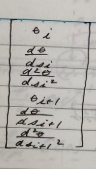 from he equation above

variable [b] (line43) is supposed to be 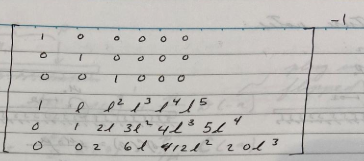 from the equation above

therefore, it follows that variable {total_coefficients_theta] (line45) would be 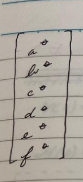 from the equation above

variables [a_theta], [b_theta], [c_theta], [d_theta], [e_theta], [f_theta] are the first, second, third, fourth, fifth, and sixth values from the variable [total_coefficients_theta]

I then plugged in variables into the given equation 

to get the function theta(s), which is represented by variable [polynomial_theta] (line59)

I then differentiated the variable [polynomial_theta] to get the functions for moment, shear, and loading represented by variables [polynomial_moment_theta] (line63), [polynomial_shear_theta] (line67), and [polynomial_loading_theta] (line73)


a=[theta_i; deriv_theta_i ; second_deriv_theta_i ; theta_iplus1 ; deriv_theta_iplus1 ; second_deriv_theta_iplus1];

b=[ 1 0 0 0 0 0 ; 0 1 0 0 0 0 ; 0 0 1 0 0 0 ; 1 l l^2 l^3 l^4 l^5 ; 0 1 2*l 3*l^2 4*l^3 5*l^4 ; 0 0 2 6*l 12*l^2 20*l^3];

total_coefficients_theta = a\b

total_coefficients_theta =     0.0003    0.0011    0.0042    0.0267    0.0372    0.0433



a_theta=total_coefficients_theta(1,1)

a_theta = 2.5996e-04


b_theta=total_coefficients_theta(1,2)

b_theta = 0.0011


c_theta=total_coefficients_theta(1,3)

c_theta = 0.0042


d_theta=total_coefficients_theta(1,4)

d_theta = 0.0267


e_theta=total_coefficients_theta(1,5)

e_theta = 0.0372


f_theta=total_coefficients_theta(1,6)

f_theta = 0.0433


polynomial_theta=a_theta + b_theta*s + c_theta*s.^2 + d_theta*s.^3 + e_theta*s.^4 + f_theta*s.^5

polynomial_theta =     0.0003    0.0004    0.0009    0.0021    0.0045    0.0089    0.0164    0.0284


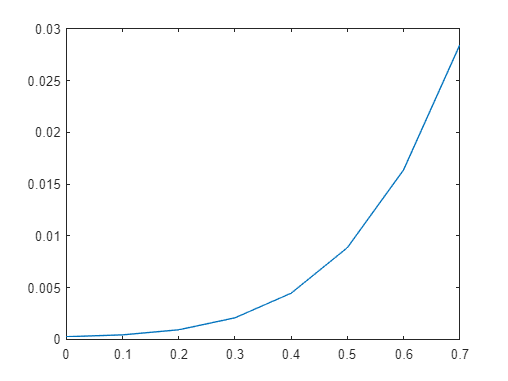


plot(s,polynomial_theta)


polynomial_moment_theta=b_theta + 2.*c_theta*s.^1 + 3.*d_theta*s.^2 + 4.*e_theta*s.^3 + 5.*f_theta*s.^4;


polynomial_shear_theta=2.*c_theta + 6.*d_theta*s.^1 + 12.*e_theta*s.^2 + 20.*f_theta*s.^3;


polynomial_loading_theta=-1.*(6.*d_theta + 24.*e_theta*s.^1 + 60.*f_theta*s.^2);




**Solving the Coupling matrix for Phi:**

It should be the same process as section "Solving the coupling matrix for theta" but replace the theta variables with the phi variables



total_phi=asin(y./(total_rho.*sin(total_theta)))

total_phi =     0.2909
    0.4138
    0.5372
    1.1070
    0.3782
    1.4301
    1.3821
    1.3952
    0.9146
    0.9000


total_deriv_phi=(total_phi(iii)-total_phi(ii))./s_interval

total_deriv_phi =    -1.2294
   -1.2343
   -5.6978
    7.2878
  -10.5183
    0.4798
   -0.1313
    4.8064
    0.1455


total_second_deriv_phi=(total_deriv_phi(iiiii)-total_deriv_phi(iiii))./s_interval

total_second_deriv_phi =    -0.0491
  -44.6350
  129.8563
 -178.0613
  109.9808
   -6.1103
   49.3766
  -46.6085


phi_i=total_phi(1,1)

phi_i = 0.2909

phi_iplus1=total_phi(end-end+2,1)

phi_iplus1 = 0.4138

deriv_phi_i=total_deriv_phi(1,1)

deriv_phi_i = -1.2294

deriv_phi_iplus1=total_deriv_phi(end-end+2,1)

deriv_phi_iplus1 = -1.2343

second_deriv_phi_i=total_second_deriv_phi(1,1)

second_deriv_phi_i = -0.0491

second_deriv_phi_iplus1=total_second_deriv_phi(end-end+2,1)

second_deriv_phi_iplus1 = -44.6350


c=[phi_i; deriv_phi_i ; second_deriv_phi_i ; phi_iplus1 ; deriv_phi_iplus1 ; second_deriv_phi_iplus1];

d=[ 1 0 0 0 0 0 ; 0 1 0 0 0 0 ; 0 0 1 0 0 0 ; 1 l l^2 l^3 l^4 l^5 ; 0 1 2*l 3*l^2 4*l^3 5*l^4 ; 0 0 2 6*l 12*l^2 20*l^3];

total_coefficients_phi= c\d

total_coefficients_phi =     0.0004   -0.0011   -0.0455   -0.0948   -0.1323   -0.1541



a_phi=total_coefficients_phi(1,1)

a_phi = 3.5311e-04


b_phi=total_coefficients_phi(1,2)

b_phi = -0.0011


c_phi=total_coefficients_phi(1,3)

c_phi = -0.0455


d_phi=total_coefficients_phi(1,4)

d_phi = -0.0948


e_phi=total_coefficients_phi(1,5)

e_phi = -0.1323


f_phi=total_coefficients_phi(1,6)

f_phi = -0.1541


polynomial_phi=a_phi + b_phi*s + c_phi*s.^2 + d_phi*s.^3 + e_phi*s.^4 + f_phi*s.^5

polynomial_phi =     0.0004   -0.0003   -0.0027   -0.0081   -0.0184   -0.0365   -0.0663   -0.1129


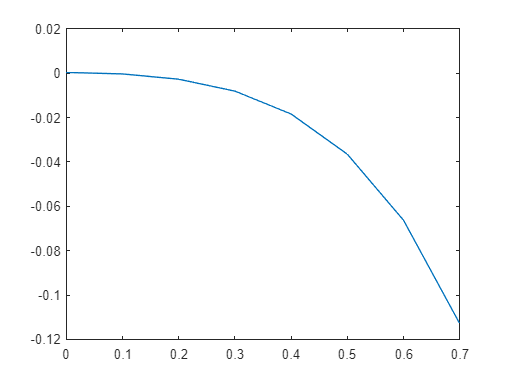


plot(s,polynomial_phi);


polynomial_moment_phi=b_phi + 2.*c_phi*s.^1 + 3.*d_phi*s.^2 + 4.*e_phi*s.^3 + 5.*f_phi*s.^4;

polynomial_shear_phi=2.*c_phi + 6.*d_phi*s.^1 + 12.*e_phi*s.^2 + 20.*f_phi*s.^3;

polynomial_loading_phi=-1.*(6.*d_phi + 24.*e_phi*s.^1 + 60.*f_phi*s.^2);



**Conservation of Moment, Forces, and Length:**

variable x_polynomial,y_polynomial, and z_polynomial is a conversion between the spherical coordinates (polynomial_theta, polynomial_phi) back to a cartesian plane

variables x_total_conserv, y_total_conserv, and z_conserv are supposed to represent the conservation of mass throughout the strings as derived in figure 7 of the paper 

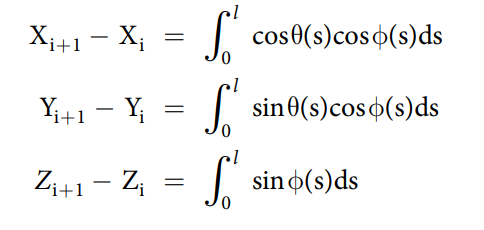

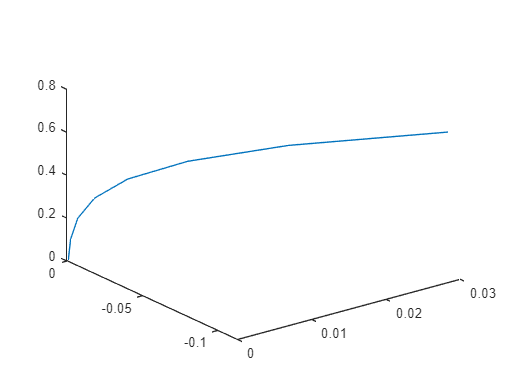


plot3(polynomial_theta, polynomial_phi,s)



x_polynomial=(cos(polynomial_theta).*cos(polynomial_phi)).*s

x_polynomial =          0    0.1000    0.2000    0.3000    0.3999    0.4996    0.5986    0.6953



y_polynomial=(sin(polynomial_theta).*cos(polynomial_phi)).*s

y_polynomial =          0    0.0000    0.0002    0.0006    0.0018    0.0044    0.0098    0.0198



z_polynomial=(sin(polynomial_phi)).*s

z_polynomial =          0   -0.0000   -0.0005   -0.0024   -0.0074   -0.0182   -0.0397   -0.0789


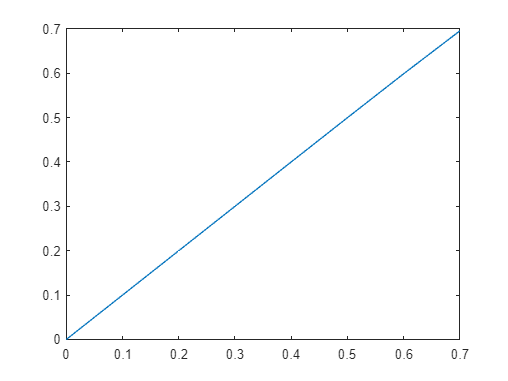


plot(s,x_polynomial)

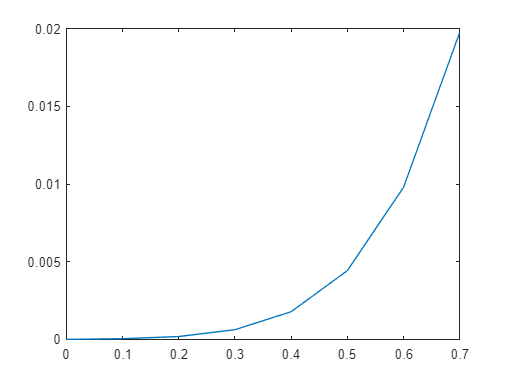


plot(s,y_polynomial)

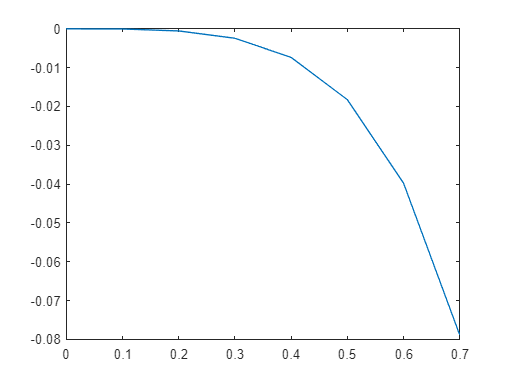


plot(s,z_polynomial)


x_total_conserv=trapz(horiz_s,x_polynomial)

x_total_conserv = 0.2446


y_total_conserv=trapz(horiz_s,y_polynomial)

y_total_conserv = 0.0027


z_total_conserv=trapz(horiz_s,z_polynomial)

z_total_conserv = -0.0108


L_u_conserv= cos(polynomial_theta-polynomial_theta(1,1)).*cos(polynomial_phi-polynomial_phi(1,1))

L_u_conserv =     1.0000    1.0000    1.0000    1.0000    0.9998    0.9993    0.9977    0.9932


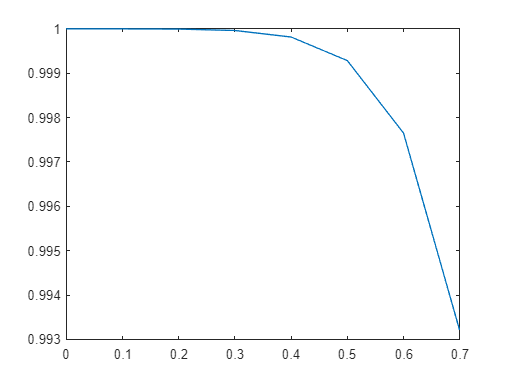


plot(s,L_u_conserv)


L_v_conserv= sin(polynomial_theta-polynomial_theta(1,1)).*cos(polynomial_phi-polynomial_phi(1,1))

L_v_conserv =          0    0.0002    0.0007    0.0018    0.0042    0.0086    0.0161    0.0280


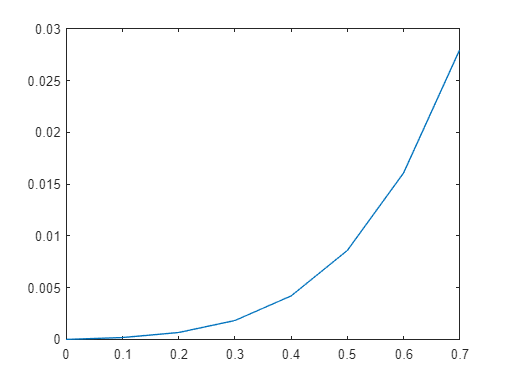


plot(s,L_v_conserv)


L_w_conserv= sin(polynomial_phi-polynomial_phi(1,1))

L_w_conserv =          0   -0.0007   -0.0031   -0.0084   -0.0187   -0.0369   -0.0666   -0.1130


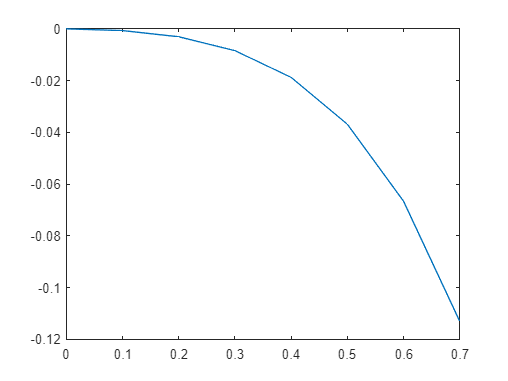


plot(s,L_w_conserv)


L_i_u=trapz(s,cos(polynomial_theta-polynomial_theta(1,1)).*cos(polynomial_phi-polynomial_phi(1,1)))

L_i_u = 0.6993


L_i_v=trapz(s,sin(polynomial_theta-polynomial_theta(1,1)).*cos(polynomial_phi-polynomial_phi(1,1)))

L_i_v = 0.0046


L_i_w=trapz(s,sin(polynomial_phi-polynomial_phi(1,1)))

L_i_w = -0.0191

Now I will be assigning boundary condition at the end of the first node, basically stating that the phi and theta at the end of the node has to be equal to the phi and theta at the start of the next segment...

end_theta = polynomial_theta(1,end)

end_theta = 0.0284

end_phi = polynomial_phi(1, end)

end_phi = -0.1129



%amount_of_segments will be the number of segments that the for loop will
%iterate through, this is supposed to be an iterative sequence for the code
%above, and it is supposed to run through the rest of the
%"total_derive_theta/phi" and "total_second_deriv_theta/phi" data to make
%the total length of the fiber



for amount_of_segments = 2:size(total_second_deriv_theta)
    nth_theta = total_theta(amount_of_segments,1)
    nth_theta_deriv = total_deriv_theta(amount_of_segments,1)
    nth_theta_second_deriv = total_second_deriv_theta(amount_of_segments,1)

    nth_theta_plus1 = total_theta(amount_of_segments+1,1)
    nth_theta_deriv_plus1 = total_deriv_theta(amount_of_segments+1,1)
    if amount_of_segments+1 <= size(total_second_deriv_theta)
        nth_theta_second_deriv_plus1 = total_second_deriv_theta(amount_of_segments+1,1)
    else
    end
    

    a=[nth_theta; nth_theta_deriv ; nth_theta_second_deriv ; nth_theta_plus1 ; nth_theta_deriv_plus1 ; nth_theta_second_deriv_plus1];

    b=[ 1 0 0 0 0 0 ; 0 1 0 0 0 0 ; 0 0 1 0 0 0 ; 1 l l^2 l^3 l^4 l^5 ; 0 1 2*l 3*l^2 4*l^3 5*l^4 ; 0 0 2 6*l 12*l^2 20*l^3];

    total_coefficients_theta = a\b;

    a_theta=nth_theta

    b_theta=total_coefficients_theta(1,2)

    c_theta=total_coefficients_theta(1,3)

    d_theta=total_coefficients_theta(1,4)

    e_theta=total_coefficients_theta(1,5)

    f_theta=total_coefficients_theta(1,6)

    polynomial_theta=a_theta + b_theta*s + c_theta*s.^2 + d_theta*s.^3 + e_theta*s.^4 + f_theta*s.^5

    nth_phi = total_phi(amount_of_segments,1)
    nth_phi_deriv = total_deriv_phi(amount_of_segments,1)
    nth_phi_second_deriv = total_second_deriv_phi(amount_of_segments,1)

    nth_phi_plus1 = total_phi(amount_of_segments+1,1)
    nth_phi_deriv_plus1 = total_deriv_phi(amount_of_segments+1,1)
    if amount_of_segments+1 <= size(total_second_deriv_phi)
        nth_phi_second_deriv_plus1 = total_second_deriv_phi(amount_of_segments+1,1)
    else
    end
    

    a=[nth_phi; nth_phi_deriv ; nth_phi_second_deriv ; nth_phi_plus1 ; nth_phi_deriv_plus1 ; nth_phi_second_deriv_plus1];

    b=[ 1 0 0 0 0 0 ; 0 1 0 0 0 0 ; 0 0 1 0 0 0 ; 1 l l^2 l^3 l^4 l^5 ; 0 1 2*l 3*l^2 4*l^3 5*l^4 ; 0 0 2 6*l 12*l^2 20*l^3];

    total_coefficients_phi = a\b;

    a_phi=nth_phi

    b_phi=total_coefficients_phi(1,2)

    c_phi=total_coefficients_phi(1,3)

    d_phi=total_coefficients_phi(1,4)

    e_phi=total_coefficients_phi(1,5)

    f_phi=total_coefficients_phi(1,6)

    polynomial_phi=a_phi + b_phi*s + c_phi*s.^2 + d_phi*s.^3 + e_phi*s.^4 + f_phi*s.^5

    plot3(polynomial_theta, polynomial_phi,s)




L_i_u, L_i_v, and L_i_w are supposed to be simplifications of the peaks in displacements for the force/moment balances later      

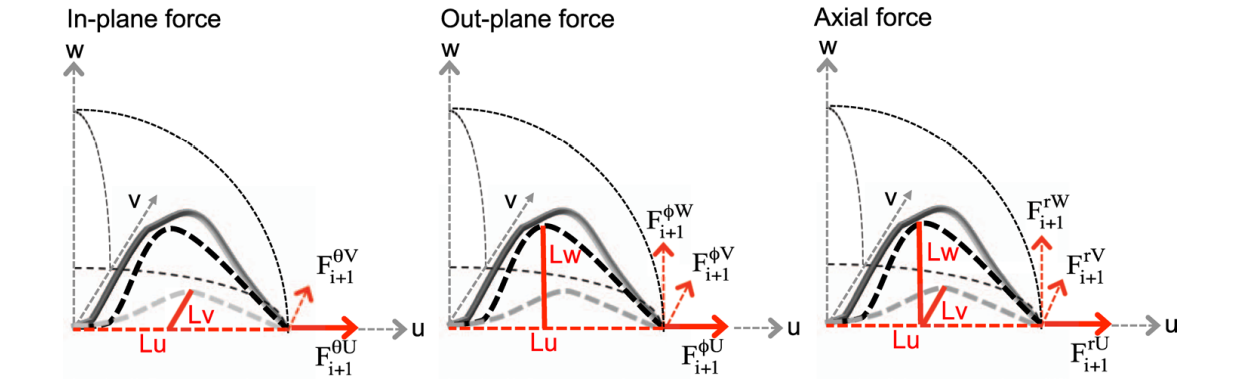

nth_theta = 0.7126

nth_theta_deriv = -0.0619

nth_theta_second_deriv = 31.3722

nth_theta_plus1 = 0.7188

nth_theta_deriv_plus1 = 3.0753

a_theta = 0.7126

b_theta = 4.2009e-04

c_theta = 0.0248

d_theta = 0.0437

e_theta = 0.0609

f_theta = 0.0708

polynomial_theta =     0.7126    0.7129    0.7141    0.7168    0.7218    0.7305    0.7446    0.7665


nth_phi = 0.4138

nth_phi_deriv = -1.2343

nth_phi_second_deriv = -44.6350

nth_phi_plus1 = 0.5372

nth_phi_deriv_plus1 = -5.6978

a_phi = 0.4138

b_phi = -7.9431e-04

c_phi = -0.0255

d_phi = -0.0411

e_phi = -0.0571

f_phi = -0.0664

polynomial_phi =     0.4138    0.4134    0.4122    0.4095    0.4046    0.3963    0.3827    0.3618


L_i_u = 0.6997

L_i_v = 0.0092

L_i_w = -0.0090

nth_theta = 0.7188

nth_theta_deriv = 3.0753

nth_theta_second_deriv = -103.5079

nth_theta_plus1 = 0.4112

nth_theta_deriv_plus1 = -7.2755

a_theta = 0.7188

b_theta = -2.1551e-04

c_theta = 0.0032

d_theta = 0.0193

e_theta = 0.0273

f_theta = 0.0320

polynomial_theta =     0.7188    0.7188    0.7191    0.7198    0.7215    0.7246    0.7300    0.7387


nth_phi = 0.5372

nth_phi_deriv = -5.6978

nth_phi_second_deriv = 129.8563

nth_phi_plus1 = 1.1070

nth_phi_deriv_plus1 = 7.2878

a_phi = 0.5372

b_phi = 1.0204e-04

c_phi = -7.4302e-04

d_phi = -0.0138

e_phi = -0.0196

f_phi = -0.0230

polynomial_phi =     0.5372    0.5372    0.5371    0.5366    0.5355    0.5334    0.5297    0.5236


L_i_u = 0.7000

L_i_v = 0.0031

L_i_w = -0.0021

nth_theta = 0.4112

nth_theta_deriv = -7.2755

nth_theta_second_deriv = 47.7790

nth_theta_plus1 = 1.1388

nth_theta_deriv_plus1 = -2.4976

a_theta = 0.4112

b_theta = -9.2345e-04

c_theta = 0.0223

d_theta = 0.0368

e_theta = 0.0516

f_theta = 0.0603

polynomial_theta =     0.4112    0.4114    0.4123    0.4145    0.4187    0.4261    0.4380    0.4567


nth_phi = 1.1070

nth_phi_deriv = 7.2878

nth_phi_second_deriv = -178.0613

nth_phi_plus1 = 0.3782

nth_phi_deriv_plus1 = -10.5183

a_phi = 1.1070

b_phi = -7.7845e-05

c_phi = -0.0092

d_phi = -0.0091

e_phi = -0.0126

f_phi = -0.0145

polynomial_phi =     1.1070    1.1069    1.1065    1.1058    1.1045    1.1023    1.0989    1.0939


L_i_u = 0.6999

L_i_v = 0.0076

L_i_w = -0.0024

nth_theta = 1.1388

nth_theta_deriv = -2.4976

nth_theta_second_deriv = 78.3207

nth_theta_plus1 = 1.3885

nth_theta_deriv_plus1 = 5.3345

a_theta = 1.1388

b_theta = 2.8113e-04

c_theta = 0.0191

d_theta = 0.0272

e_theta = 0.0378

f_theta = 0.0440

polynomial_theta =     1.1388    1.1390    1.1399    1.1417    1.1451    1.1508    1.1600    1.1741


nth_phi = 0.3782

nth_phi_deriv = -10.5183

nth_phi_second_deriv = 109.9808

nth_phi_plus1 = 1.4301

nth_phi_deriv_plus1 = 0.4798

a_phi = 0.3782

b_phi = -4.9021e-04

c_phi = -0.0025

d_phi = -0.0179

e_phi = -0.0251

f_phi = -0.0293

polynomial_phi =     0.3782    0.3781    0.3778    0.3771    0.3755    0.3726    0.3676    0.3596


L_i_u = 0.6999

L_i_v = 0.0062

L_i_w = -0.0030

nth_theta = 1.3885

nth_theta_deriv = 5.3345

nth_theta_second_deriv = -19.7413

nth_theta_plus1 = 0.8551

nth_theta_deriv_plus1 = 3.3604

a_theta = 1.3885

b_theta = 0.0012

c_theta = 0.0201

d_theta = 0.0469

e_theta = 0.0653

f_theta = 0.0760

polynomial_theta =     1.3885    1.3889    1.3901    1.3927    1.3977    1.4065    1.4210    1.4438


nth_phi = 1.4301

nth_phi_deriv = 0.4798

nth_phi_second_deriv = -6.1103

nth_phi_plus1 = 1.3821

nth_phi_deriv_plus1 = -0.1313

a_phi = 1.4301

b_phi = 2.0993e-04

c_phi = -0.0261

d_phi = -0.0528

e_phi = -0.0740

f_phi = -0.0863

polynomial_phi =     1.4301    1.4298    1.4285    1.4255    1.4198    1.4097    1.3931    1.3670


L_i_u = 0.6997

L_i_v = 0.0093

L_i_w = -0.0105

nth_theta = 0.8551

nth_theta_deriv = 3.3604

nth_theta_second_deriv = -75.5799

nth_theta_plus1 = 0.5191

nth_theta_deriv_plus1 = -4.1976

a_theta = 0.8551

b_theta = -3.6122e-05

c_theta = 0.0069

d_theta = 0.0270

e_theta = 0.0381

f_theta = 0.0445

polynomial_theta =     0.8551    0.8552    0.8557    0.8569    0.8593    0.8640    0.8718    0.8844


nth_phi = 1.3821

nth_phi_deriv = -0.1313

nth_phi_second_deriv = 49.3766

nth_phi_plus1 = 1.3952

nth_phi_deriv_plus1 = 4.8064

a_phi = 1.3821

b_phi = 6.5023e-04

c_phi = -0.0116

d_phi = -0.0373

e_phi = -0.0526

f_phi = -0.0616

polynomial_phi =     1.3821    1.3820    1.3813    1.3797    1.3761    1.3696    1.3586    1.3411


L_i_u = 0.6999

L_i_v = 0.0047

L_i_w = -0.0066

nth_theta = 0.5191

nth_theta_deriv = -4.1976

nth_theta_second_deriv = 54.8803

nth_theta_plus1 = 0.9388

nth_theta_deriv_plus1 = 1.2904

a_theta = 0.5191

b_theta = -2.1616e-04

c_theta = 0.0220

d_theta = 0.0349

e_theta = 0.0487

f_theta = 0.0568

polynomial_theta =     0.5191    0.5193    0.5203    0.5224    0.5265    0.5336    0.5451    0.5629


nth_phi = 1.3952

nth_phi_deriv = 4.8064

nth_phi_second_deriv = -46.6085

nth_phi_plus1 = 0.9146

nth_phi_deriv_plus1 = 0.1455

a_phi = 1.3952

b_phi = 6.6374e-04

c_phi = -0.0242

d_phi = -0.0393

e_phi = -0.0550

f_phi = -0.0642

polynomial_phi =     1.3952    1.3950    1.3940    1.3916    1.3870    1.3791    1.3663    1.3464


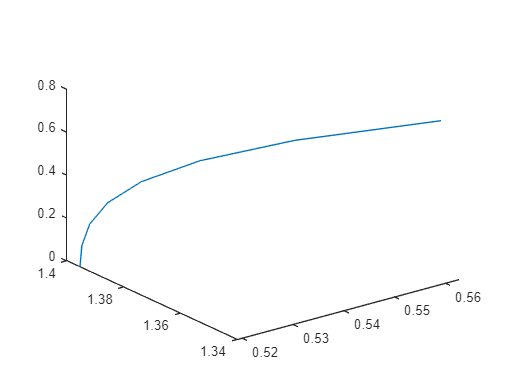

L_i_u = 0.6998

L_i_v = 0.0075

L_i_w = -0.0083

    L_i_u=trapz(s,cos(polynomial_theta-polynomial_theta(1,1)).*cos(polynomial_phi-polynomial_phi(1,1)))

    L_i_v=trapz(s,sin(polynomial_theta-polynomial_theta(1,1)).*cos(polynomial_phi-polynomial_phi(1,1)))

    L_i_w=trapz(s,sin(polynomial_phi-polynomial_phi(1,1)))


 

end